Call the Summary Table

LatexPlots
load SummTable
% Delete Analysis for the Last scale factor
filter1 = find(SummTable.hazlvl >= 2);
SummTable(filter1, :) = [];
% SummTable = SummTable

Plot of PGA vs Derailments

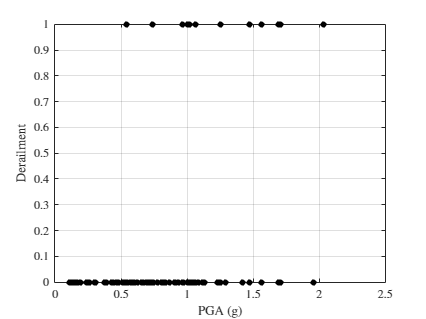


plot(SummTable.pga/9.81, SummTable.drcase, 'k.', 'MarkerSize', 15.0), grid on, xlabel('PGA (g)'), ylabel('Derailment')

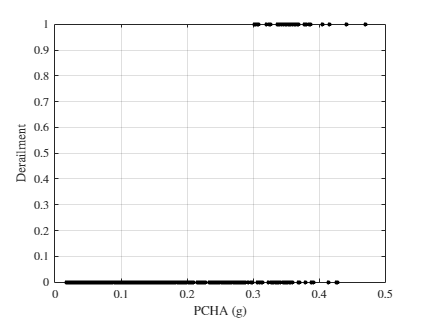

plot(SummTable.pcha/9.81, SummTable.drcase, 'k.', 'MarkerSize', 10.0), grid on, xlabel('PCHA (g)'), ylabel('Derailment')

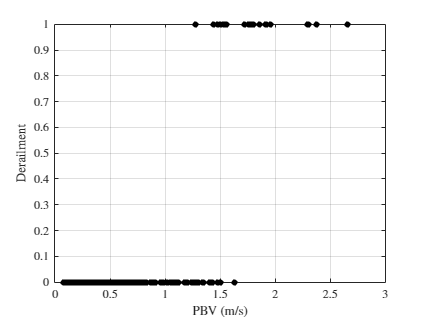

plot(SummTable.pbv, SummTable.drcase, 'k.', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')

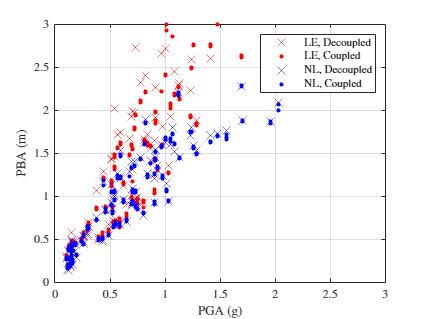

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBA (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 3, 0, 3])
grid on

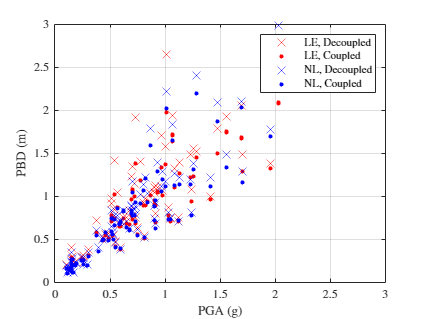

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pbd / 6 * 100, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pbd / 6 * 100, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pbd / 6 * 100, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pbd / 6 * 100, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

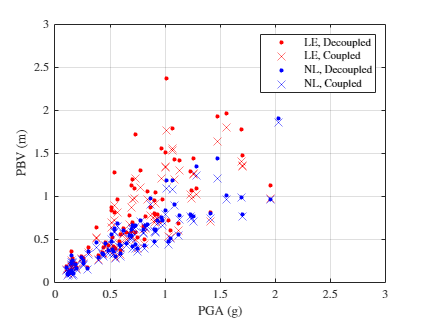

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pbv, 'r.', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pbv, 'rx', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pbv, 'b.', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pbv, 'bx','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBV (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

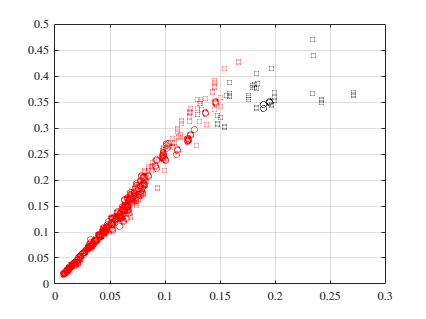

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0));  % Nonlinear, Coupled
plot(SummTable(indices1,:).pbv/9.81, SummTable(indices1,:).pcha/9.81, 'rs', ...
     SummTable(indices2,:).pbv/9.81, SummTable(indices2,:).pcha/9.81, 'ro', ...
     SummTable(indices3,:).pbv/9.81, SummTable(indices3,:).pcha/9.81, 'ks', ...
     SummTable(indices4,:).pbv/9.81, SummTable(indices4,:).pcha/9.81, 'ko','MarkerSize', 5.0)
grid on

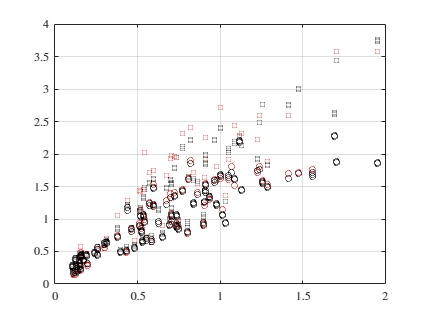

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rs', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'ro', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'ks', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'ko','MarkerSize', 5.0), grid

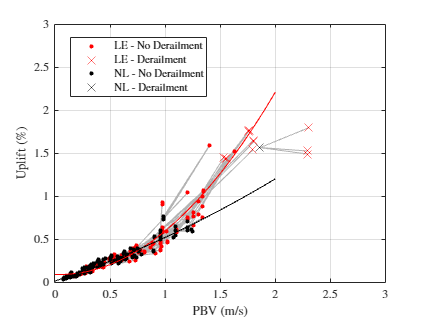

close all
cfac = 1.0;
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac));  % Nonlinear, Coupled

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac));
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac));


peakrot = deg2rad(0.836);

pfit1 = polyfit(SummTable(indices1,:).pbv, SummTable(indices1,:).purot, 2);
pfit2 = polyfit(SummTable(indices3,:).pbv, SummTable(indices3,:).purot, 2);

for i = 1:length(indices6)
    plot([SummTable(indices5(i),:).pbv, SummTable(indices6(i),:).pbv], [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, '-', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.7, 0.7, 0.7]), hold on
end

plot(SummTable(indices1,:).pbv, SummTable(indices1,:).purot/peakrot, 'r.', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).purot/peakrot, 'k.', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 10.0)

plot(0:0.1:2, polyval(pfit1, 0:0.1:2)/peakrot, 'r', ...
     0:0.1:2, polyval(pfit2, 0:0.1:2)/peakrot, 'k'), axis([0 3 0 3])

grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='best'), xlabel('PBV (m/s)'), ylabel('Uplift (\%)')

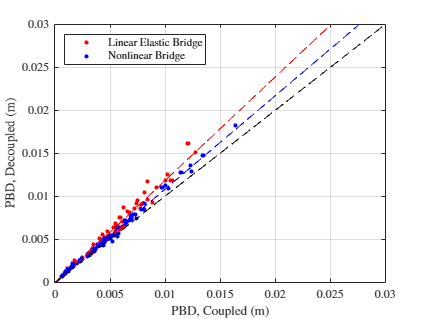

% Coupled/Decoupled 
close all
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled


reg1 = polyfit(SummTable(indices1,:).pbd / 9.81, SummTable(indices3,:).pbd / 9.81, 1);
reg2 = polyfit(SummTable(indices2,:).pbd / 9.81, SummTable(indices4,:).pbd / 9.81, 1);


plot(SummTable(indices1,:).pbd / 9.81, SummTable(indices3,:).pbd / 9.81, 'r.', ...
     SummTable(indices2,:).pbd / 9.81, SummTable(indices4,:).pbd / 9.81, 'b.', ...
     [0, 3], polyval(reg1, [0,3]), 'r--', ...
     [0, 3], polyval(reg2, [0,3]), 'b--', ...
     [0, 3], [0, 3], 'k--', MarkerSize=10.0), axis([0 0.03 0 0.03]), xlabel('PBD, Coupled (m)'), ylabel('PBD, Decoupled (m)'), grid on, legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')

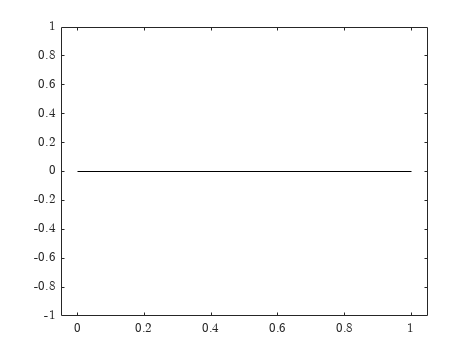

figure()
histogram()